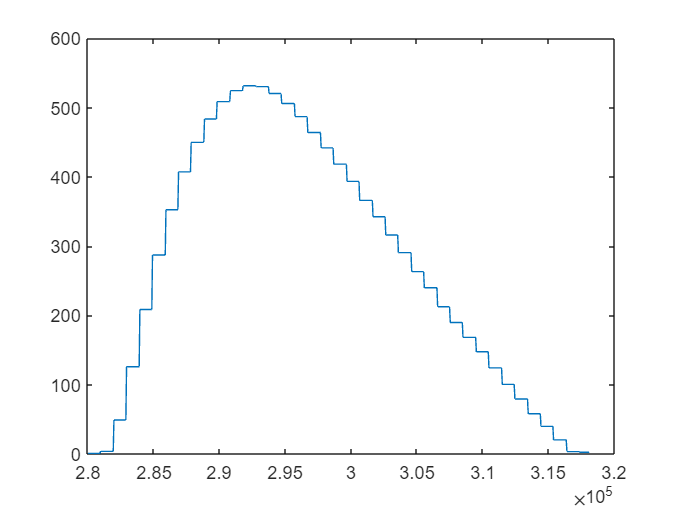

% making fake data for x^2.
% Ts = [1,2,3,4,5];
% As = [1,4,9,16,25];
% 
% polyfit(Ts,As,2);
% 
% y = ([sum(Ts.^4), sum(Ts.^3), sum(Ts.^2); sum(Ts.^3), sum(Ts.^2), sum(Ts.^1); sum(Ts.^2), sum(Ts), 5]);
% z = [sum(As.*(Ts.^2)); sum(As.*(Ts.^1)); sum(As)];                
% result = y\z;
% 
% y = ([5, sum(Ts), sum(Ts.^2); sum(Ts.^1), sum(Ts.^2), sum(Ts.^3); sum(Ts.^2), sum(Ts.^3), sum(Ts.^4)]);
% z = [sum(As); sum(As.*(Ts.^1)); sum(As.*(Ts.^2))];                
% result = (y.^-1) * z;
% 
% diff = polyder(result);
% tguess = -diff(2)/(diff(1));
% ag2 = polyval(result,tguess);

clear 
clc 
refpressure = 101728.25;

data = readmatrix("astra2_air.txt");
for i = 1: length(data) 
    alldata(i,1) = data(i,1); % Adding each time datapoint onto the end of all data array. 
    alldata(i,2) = data(i,2); % pressure point.
    alldata(i,3) = (44330 * (1 - (alldata(i,2)/refpressure)^(1/5.255))); 
end 

plot(alldata(:,1),alldata(:,3))